Starting by importing the image into matlabs

img = imread("Clocktower.jpg")

img = 1280×960×3 uint8 array
img(:,:,1) =

   218   218   218   218   218   218   218   218   218   218   218   218   218   218   218   217   217   216   216   216   216   216   216   216   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   215   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   212   210   210   210   210   210   210   210   210   212   212   211   211   211   211   209   209   208   208   206   206   206   206   205   205   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   206   204   204   204   204   204   204   204   

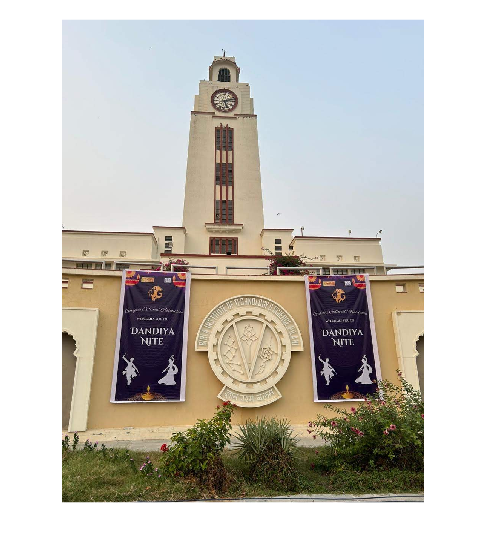

imshow(img)

blockSize = 4 %defining the size of our convolution matrix

blockSize = 4

Now we'll split up our image into the R, G and B values

imgBinned = zeros(size(img,1)/blockSize, size(img,2)/blockSize, size(img,3), "uint8")

imgBinned = 320×240×3 uint8 array
imgBinned(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

Now let's start iterating through the original img matrix

for i=1:blockSize:size(img,1)
    for j=1:blockSize:size(img,2)
        for k=1:1:size(img,3)
            tempSubMatrix = img(i:i+blockSize-1, j:j+blockSize-1, k); %BIG NOTE: don't remove the semicolon otherwise the program takes forever to compile because it prints EVERY matrix
            imgBinned(i,j,k) = ceil(mean(mean(tempSubMatrix)));
        end
    end
end

Fixing the fact that the loop is messed up somewhere and I'm too lazy to actually fix it, so we just remove every other line 🤡

imgBinned

imgBinned = 1277×957×3 uint8 array
imgBinned(:,:,1) =

   218     0     0     0   218     0     0     0   218     0     0     0   218     0     0     0   217     0     0     0   216     0     0     0   215     0     0     0   215     0     0     0   215     0     0     0   215     0     0     0   215     0     0     0   215     0     0     0   212     0     0     0   212     0     0     0   212     0     0     0   212     0     0     0   212     0     0     0   212     0     0     0   212     0     0     0   212     0     0     0   212     0     0     0   212     0     0     0   212     0     0     0   212     0     0     0   212     0     0     0   212     0     0     0   210     0     0     0   210     0     0     0   212     0     0     0   210     0     0     0   207     0     0     0   206     0     0     0   206     0     0     0   206     0     0     0   206     0     0     0   206     0     0     0   206     0     0     0   206     0     0     0   204     0     0     0   204   

imgBinned = imgBinned(1:blockSize:end,1:blockSize:end,:) %I'm proud of myself for actually figuring this out lmao 😎

imgBinned = 320×240×3 uint8 array
imgBinned(:,:,1) =

   218   218   218   218   217   216   215   215   215   215   215   215   212   212   212   212   212   212   212   212   212   212   212   212   212   212   210   210   212   210   207   206   206   206   206   206   206   206   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   203   202   202   202   202   202   202   202   202   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   199   199   199   199   199   199   199   199   199   199   199   199   199   199   200   199   198   198   198   198   198   198   198   198   198   198   198   198   197   197   198   196   197   197   197   197   194   194   194   194   197   197   197   197   195   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   195   195   194   194   194   194   193   193   193   193   193   1

imgBinned

imgBinned = 320×240×3 uint8 array
imgBinned(:,:,1) =

   218   218   218   218   217   216   215   215   215   215   215   215   212   212   212   212   212   212   212   212   212   212   212   212   212   212   210   210   212   210   207   206   206   206   206   206   206   206   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   204   203   202   202   202   202   202   202   202   202   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   201   199   199   199   199   199   199   199   199   199   199   199   199   199   199   200   199   198   198   198   198   198   198   198   198   198   198   198   198   197   197   198   196   197   197   197   197   194   194   194   194   197   197   197   197   195   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   194   195   195   194   194   194   194   193   193   193   193   193   1

Showing the actual image and comparing

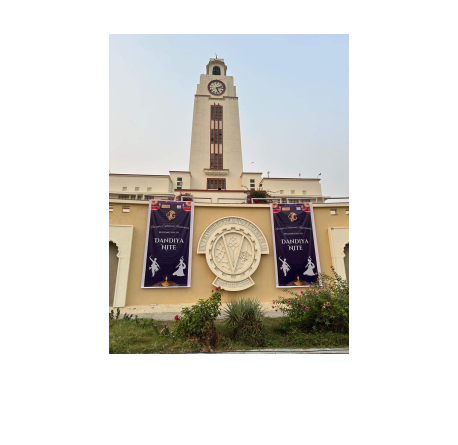

imshow(imgBinned)

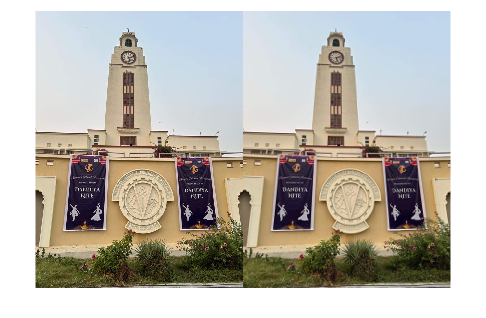

montage({img, imgBinned}, 'Size', [1 2])